clear;
clc;
rng(2024);
n = 1024;
k = 25;
B = 2^round(log(round(sqrt(n*k)))/log(2));%使得B是2的幂次，保证整除
delta = 1/n;%暂定
d = 2;
L = 5*round(log(n)/log(2));
theta = 2/3; % 自己添加的参数，超过theta*L次后认为存在这一值
w = min(n,round(B*log(n/delta)));

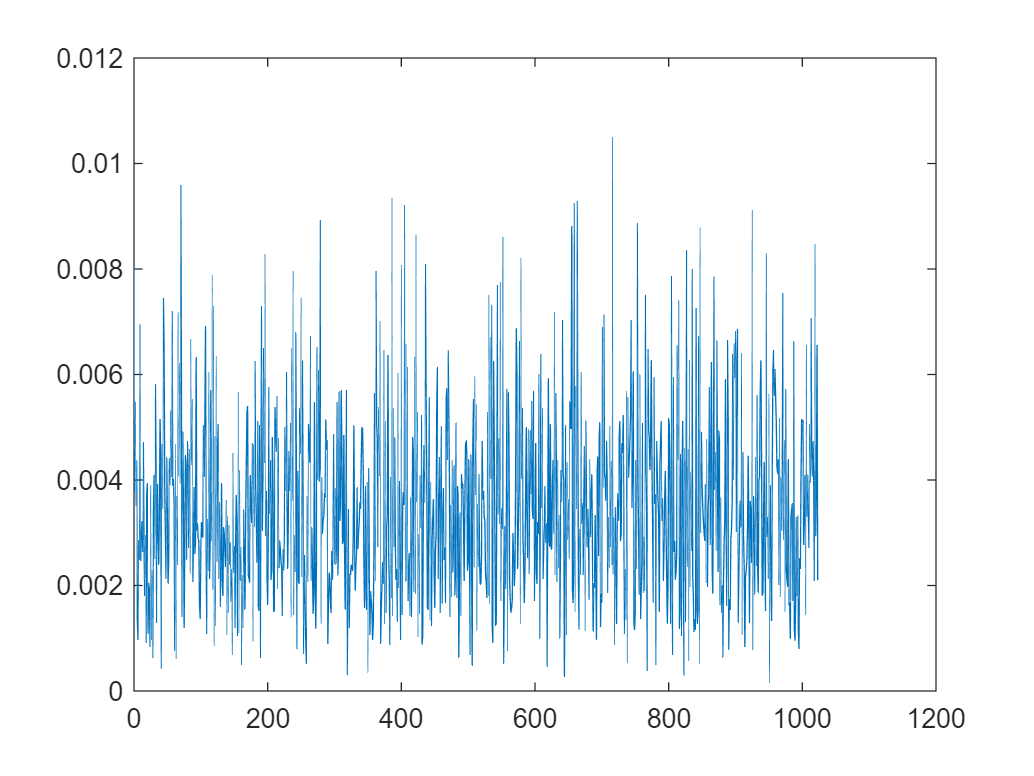


[x,t,k_list] = generate_sparse(n,k,0.5,1,0.01);
x_f = fft(x);
figure;
plot(t,abs(x));

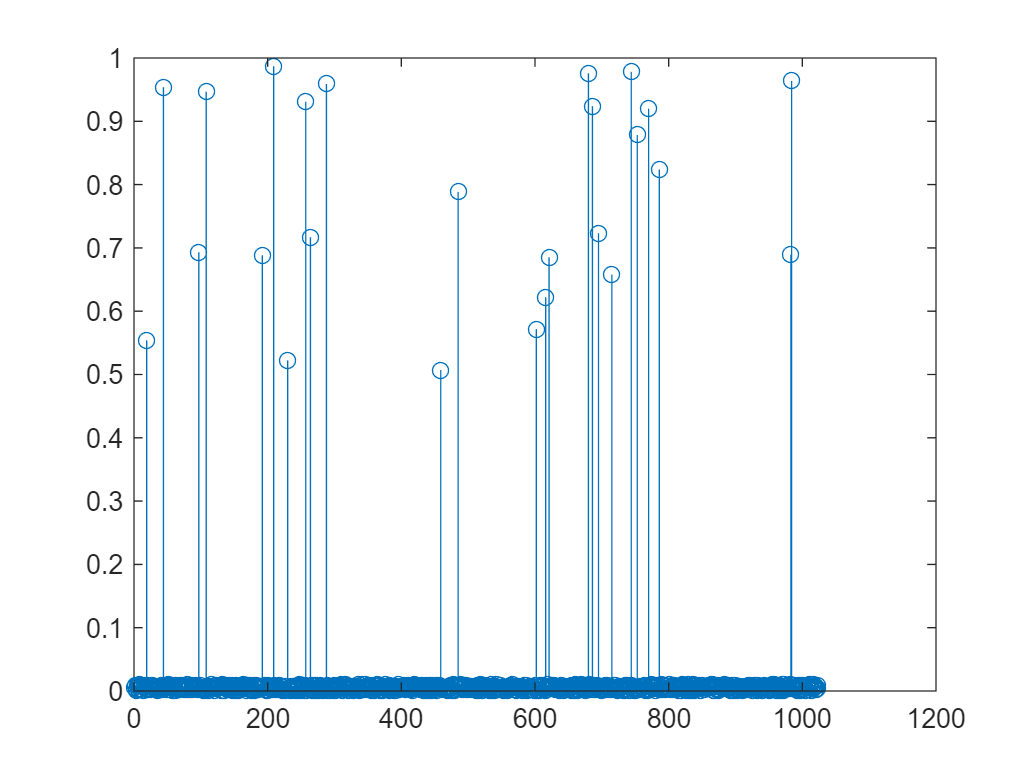

figure;
stem(t,abs(x_f));

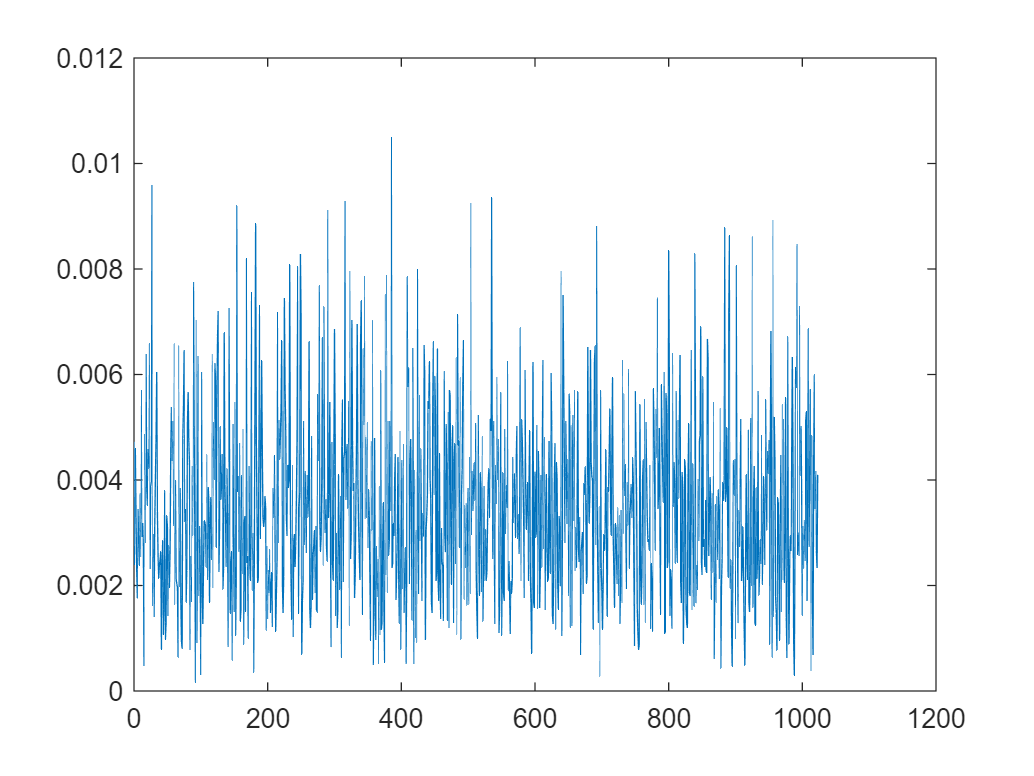

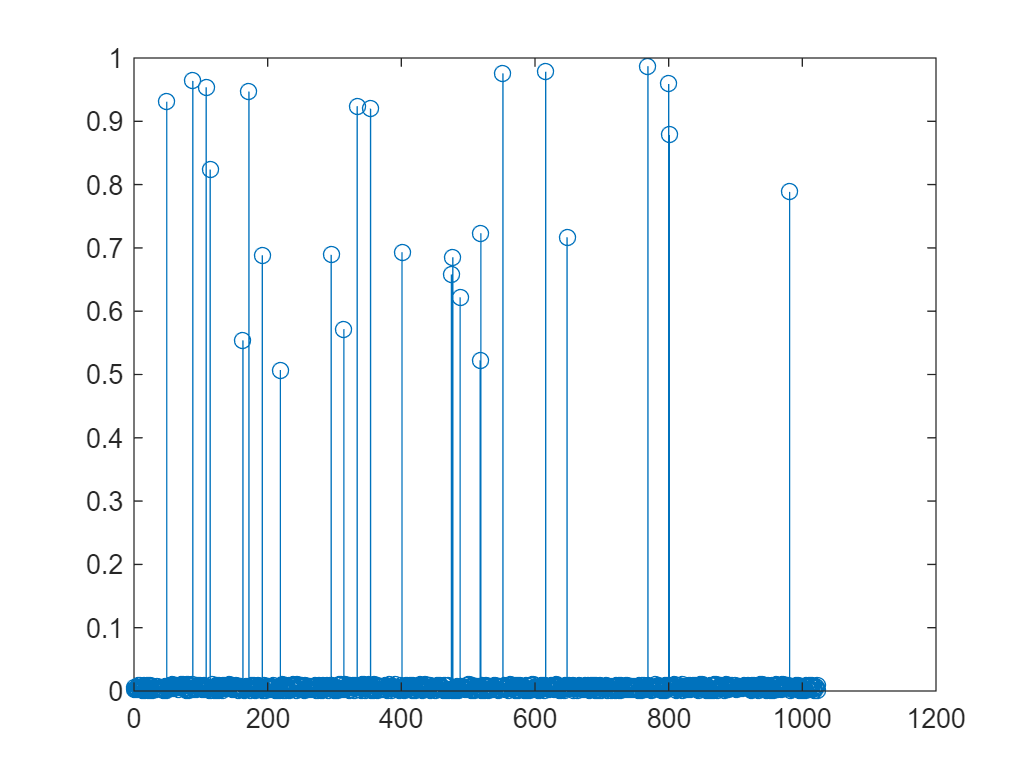

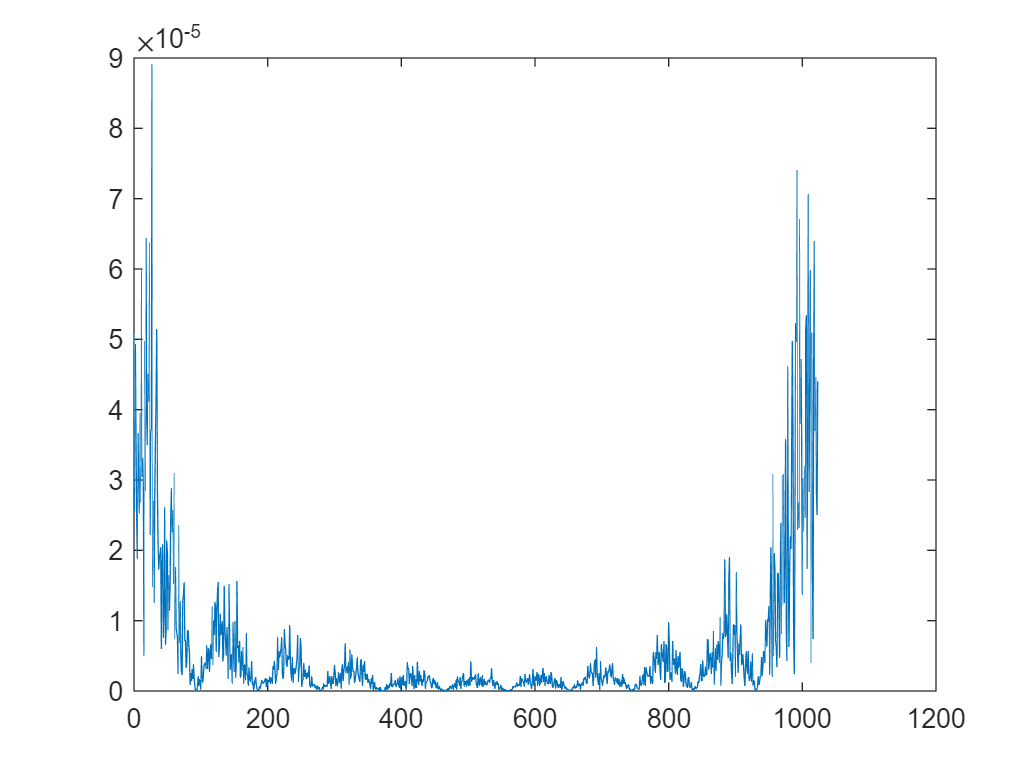

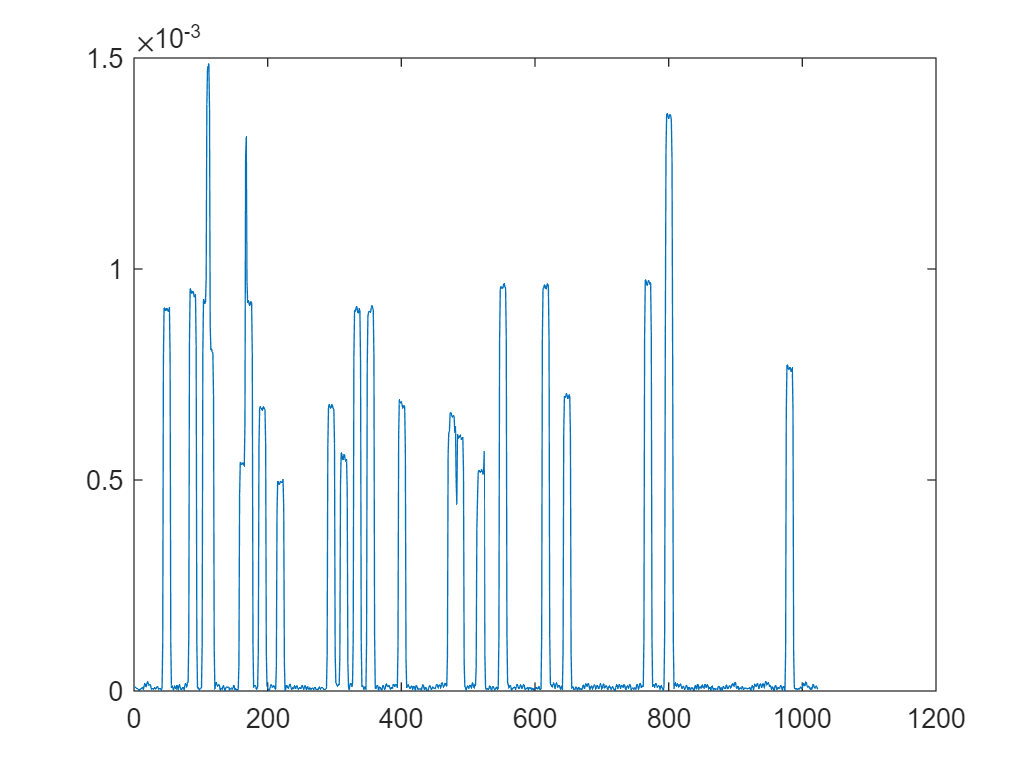

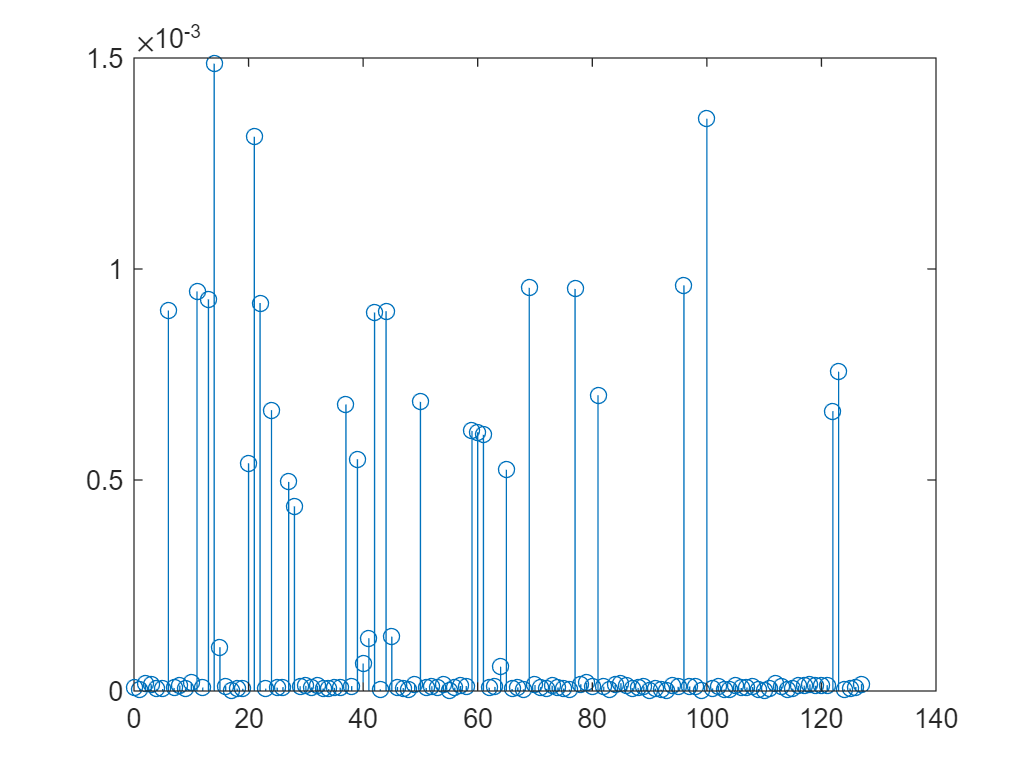

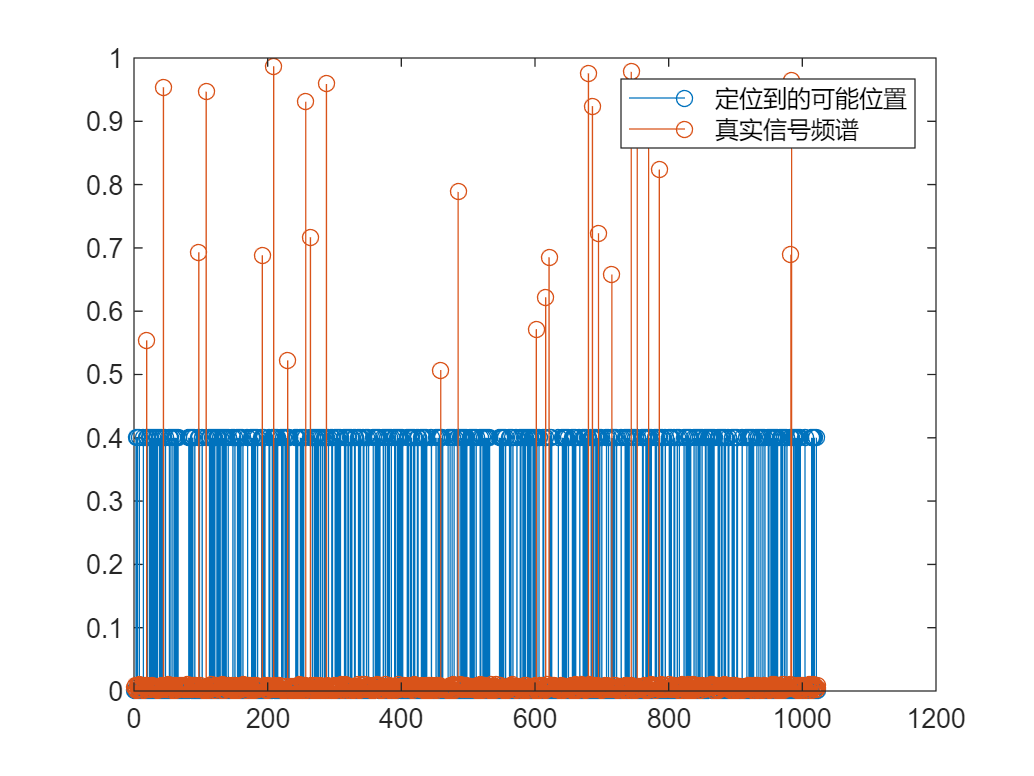


tic;
loc_loop = zeros(1,n);

% 先进行定位循环
for count = 1:1:L
    % step1:permute,将大频点打乱
    sigma = randi([0,n/2-1])*2+1;%必须是奇数以保证有逆
    tau = randi([0,n-1]);
    x_p = zeros(size(x));
    for ii = 1:1:n
        x_p(ii) = x(mod(sigma*(ii-1)+tau,n)+1);
    end
    x_f_p = fft(x_p);
    if count==1
        figure;
        plot(t,abs(x_p));
        figure;
        stem(t,abs(x_f_p));
    end
    
    % step2:卷上频域窗函数
    [g_window,~,g_window_f] = gauss_window(n,1/(2*B),1/B,delta,min(n,round(B*log(n/delta))));
    x_g = g_window.*x_p;
    x_f_g = fft(x_g);
    if count==1
        figure;
        plot(t,abs(x_g));
        figure;
        plot(t,abs(x_f_g));
    end
    
    % step3:频域降采样
    y = zeros(1,B);
    for ii = 1:1:B
        y(ii) = sum(x_g(ii:B:end));
    end
    z = fft(y);
    if count==1
        figure;
        stem(0:1:B-1,abs(z));
    end
    
    % 找到幅度最大的d*k个
    [~,J] = maxk(abs(z),d*k);
    for ii = 1:1:length(J)
        list = inv_hash(n,sigma,B,J(ii)-1)+1;
        list = list(list>0);
        loc_loop(list) = loc_loop(list)+1;
    end

    if count==1
        figure;
        stem(0:1:n-1,abs(loc_loop)*0.4);
        hold on;
        stem(0:1:n-1,abs(x_f));
        legend(["定位到的可能位置","真实信号频谱"])
    end
end

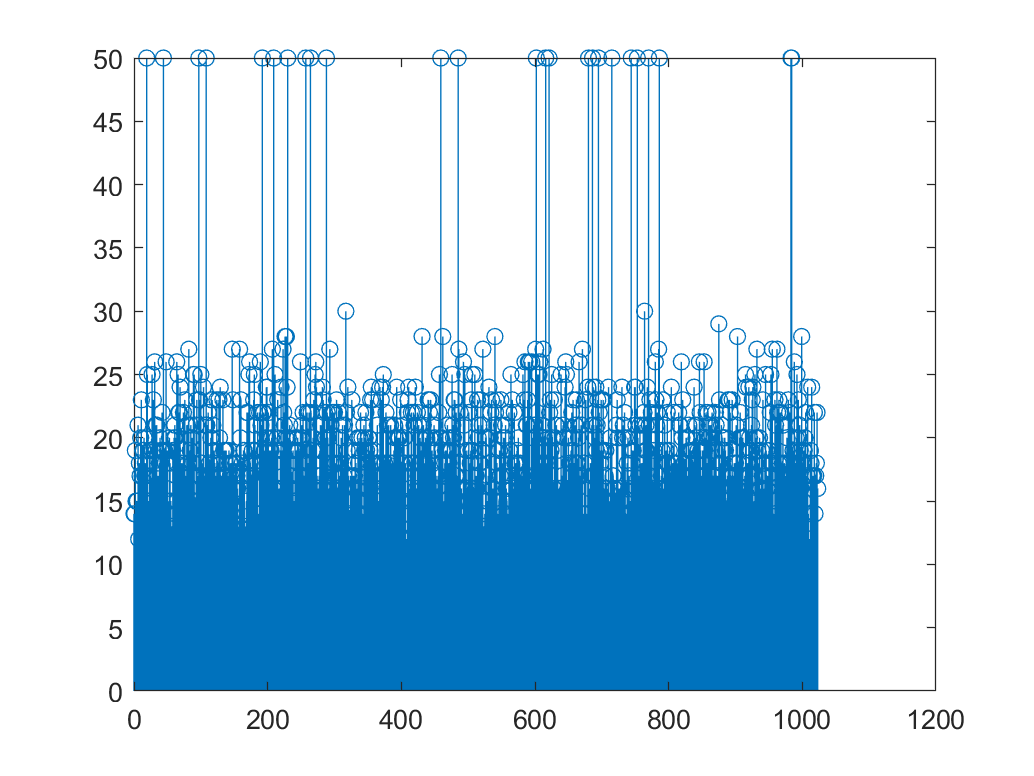

figure;
stem(0:1:n-1,loc_loop);

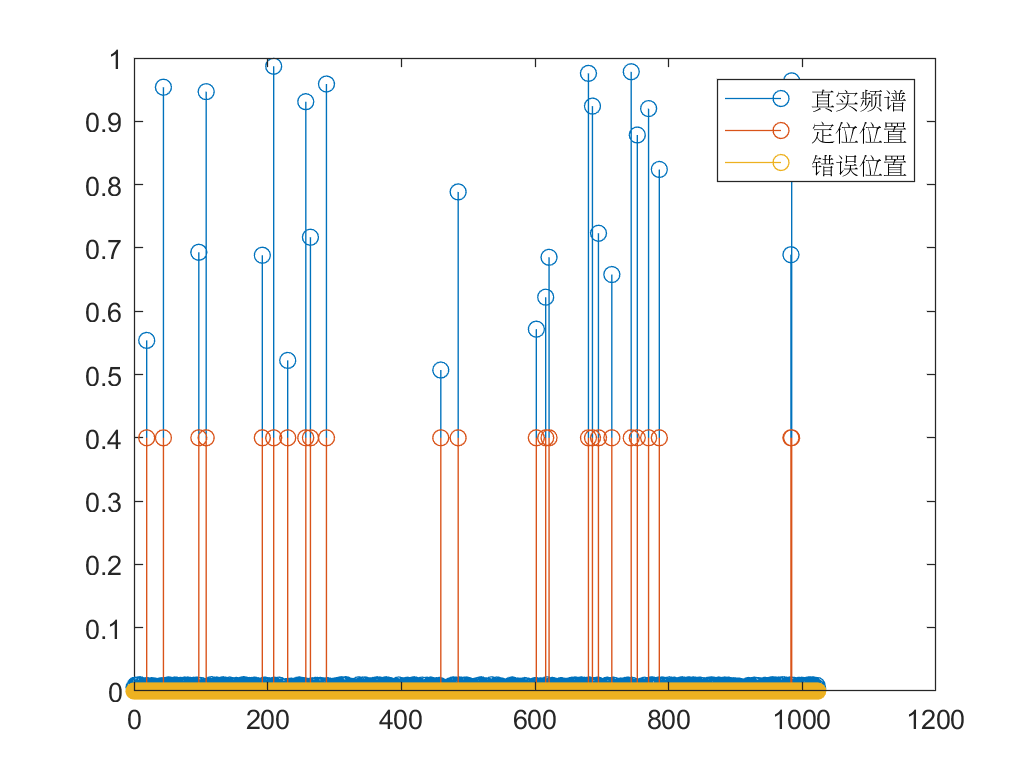

loc_loop(loc_loop<theta*L) = 0;
loc_loop(loc_loop>=theta*L) = 1;
wrong = ((loc_loop==1&abs(x_f)<0.5)|(loc_loop==0&abs(x_f)>=0.5))*0.3;
figure;
stem(t,abs(x_f));
hold on;
stem(0:1:n-1,loc_loop*0.4)
stem(0:1:n-1,wrong)
legend(["真实频谱","定位位置","错误位置"])

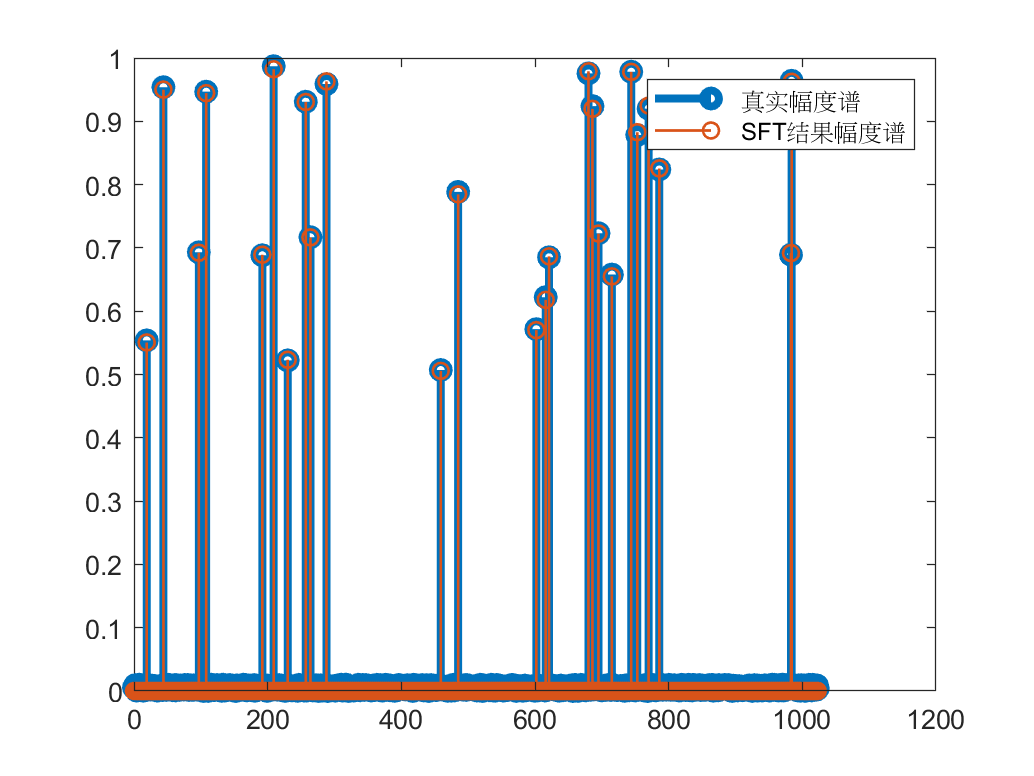


list = find(loc_loop);
est_loop = zeros(length(list),L);

% 再进行值判决，多次循环取中间值！（去除频点过于接近导致的错误值）
for count = 1:1:L
    % step1:permute,将大频点打乱
    sigma = randi([0,n/2-1])*2+1;%必须是奇数以保证有逆
    tau = randi([0,n-1]);
    x_p = zeros(size(x));
    for ii = 1:1:length(x)
        x_p(ii) = x(mod(sigma*(ii-1)+tau,n)+1);
    end
    x_f_p = fft(x_p);
    %stem(t,abs(x_f_p));
    
    % step2:卷上频域窗函数
    [g_window,~,g_window_f] = gauss_window(n,1/(2*B),1/B,delta,min(n,round(B*log(n/delta))));
    x_g = g_window.*x_p*n;%为了保证卷积，再乘以n
    x_f_g = fft(x_g);
    %figure;
    %plot(t,abs(x_f_g));
    
    % step3:频域降采样
    y = zeros(1,B);
    for ii = 1:1:B
        y(ii) = sum(x_g(ii:B:end));
    end
    z = fft(y);
    figure;
    %stem(0:1:B-1,abs(z));
    
    % 估计大小
    est_loop(:,count) = z(hash(n,sigma,B,list-1)+1).*exp(-1i*2*pi*tau.*(list-1)/n)./g_window_f(1+mod(mod(sigma*(list-1),n)-round((hash(n,sigma,B,list-1))*(n/B)),n));
end
est_loop= sort(est_loop,2);
x_est = zeros(1,n);
x_est(list) = est_loop(:,round(L/2));
figure;
stem(0:1:n-1,abs(x_f),"linewidth",3)
hold on;
stem(0:1:n-1,abs(x_est),"linewidth",1)
legend(["真实幅度谱","SFT结果幅度谱"])

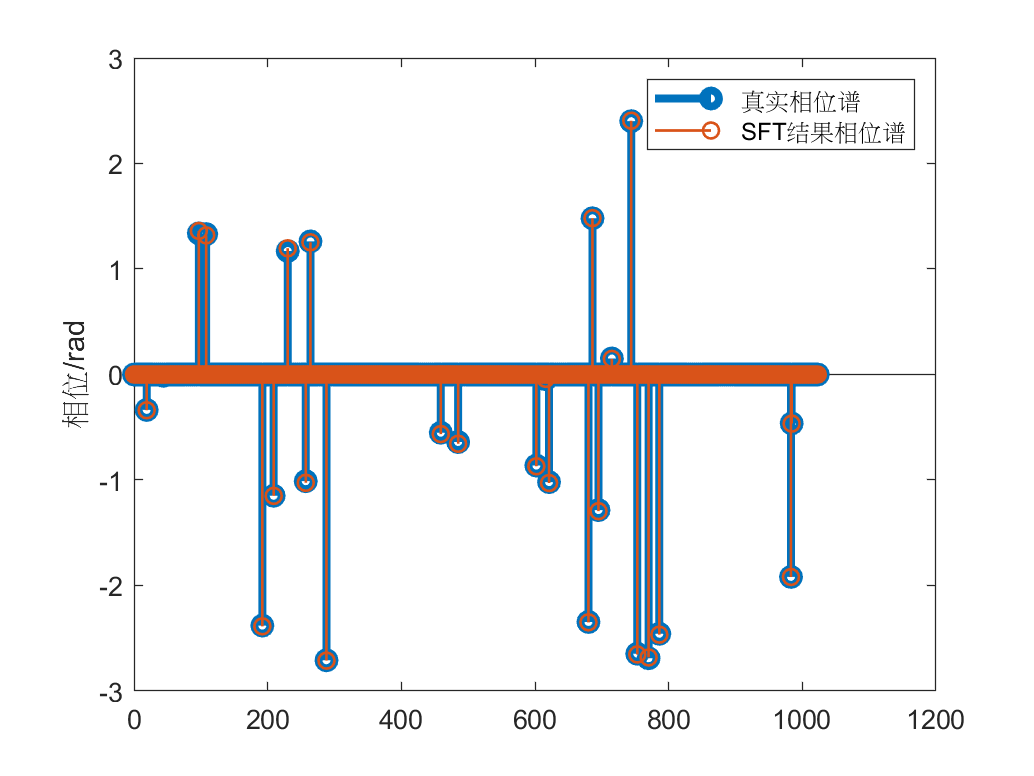


figure;
stem(0:1:n-1,angle(x_f),"linewidth",3)
hold on;
stem(0:1:n-1,angle(x_est),"linewidth",1)
ylabel("相位/rad")
legend(["真实相位谱","SFT结果相位谱"])


toc;

历时 0.974515 秒。
